CODE FOR BRAIN EXTRACTION

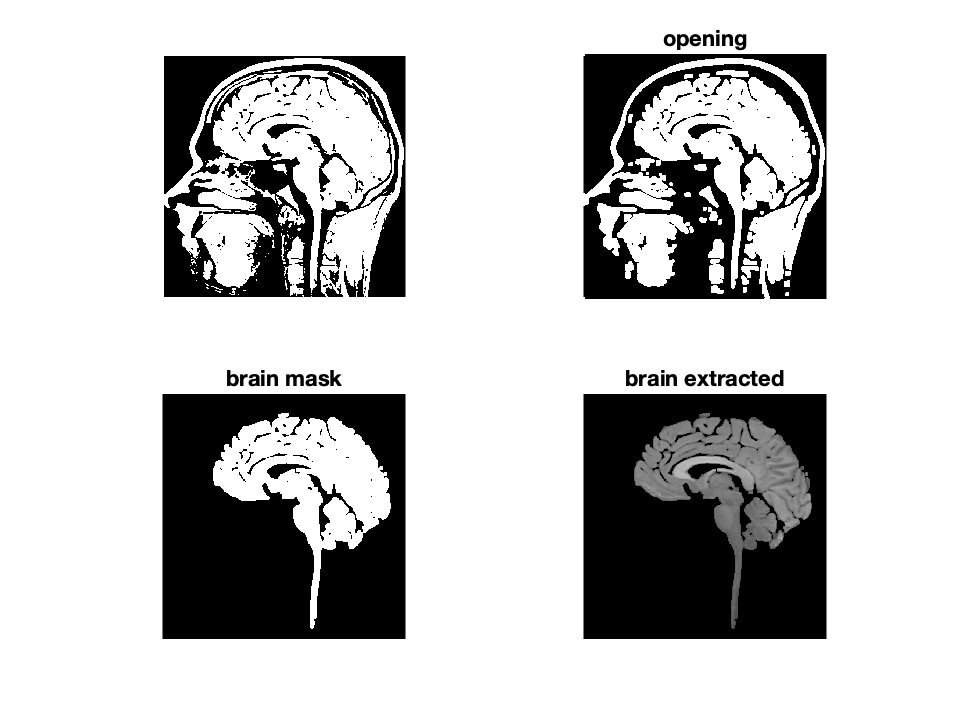

clc;
close all;
clear all;
k=imread("/Users/aaditya/Desktop/mriii.png");
k=rgb2gray(k);
figure(1);
subplot(221);imshow(k,[]);title('brain image')
k1=im2bw(k,graythresh(k));
imshow(k1);
SE=strel('disk',7);  
    k2=imopen(k1,SE); 
subplot(222);imshow(k2);title('opening')
b=bwlabel(k2);
imtool(b,[]);
b(b~=10)=0;
subplot(223);imshow(b);title('brain mask') 
for i =1:912
    for j =1:904

        if((b(i,j))==0)
            k(i,j)=0;
        else
            k(i,j)=k(i,j);
    end
    end
end
subplot(224);imshow(k);title('brain extracted')

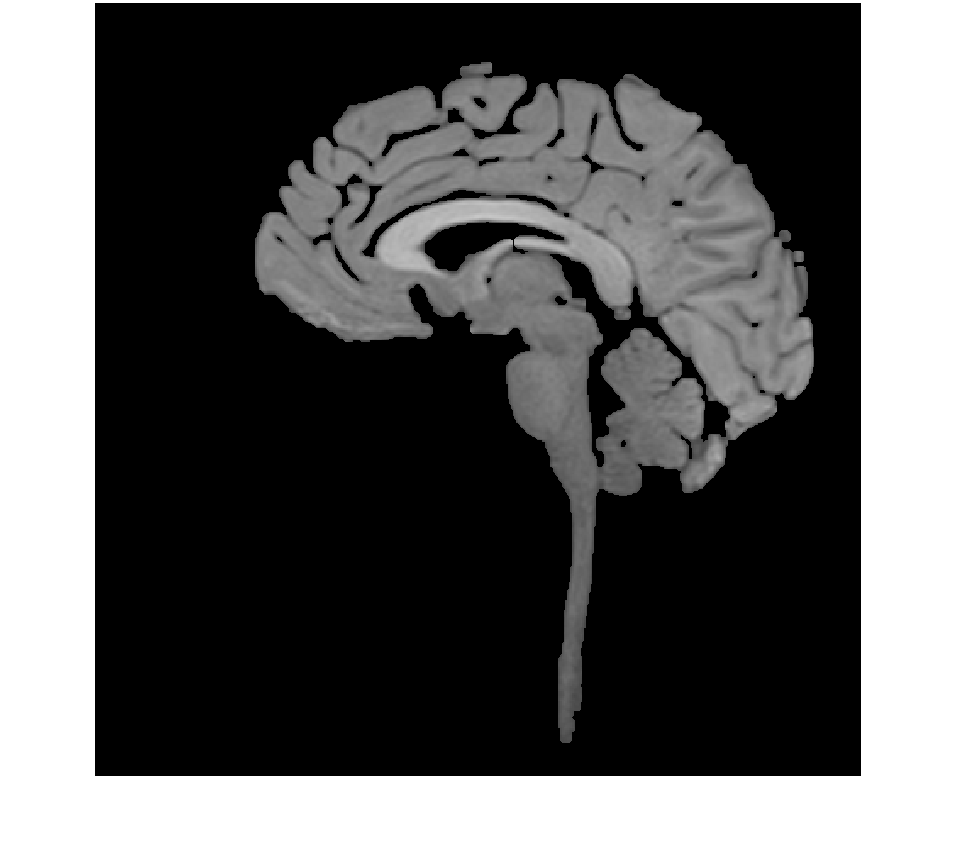

figure(2),
imshow(k)